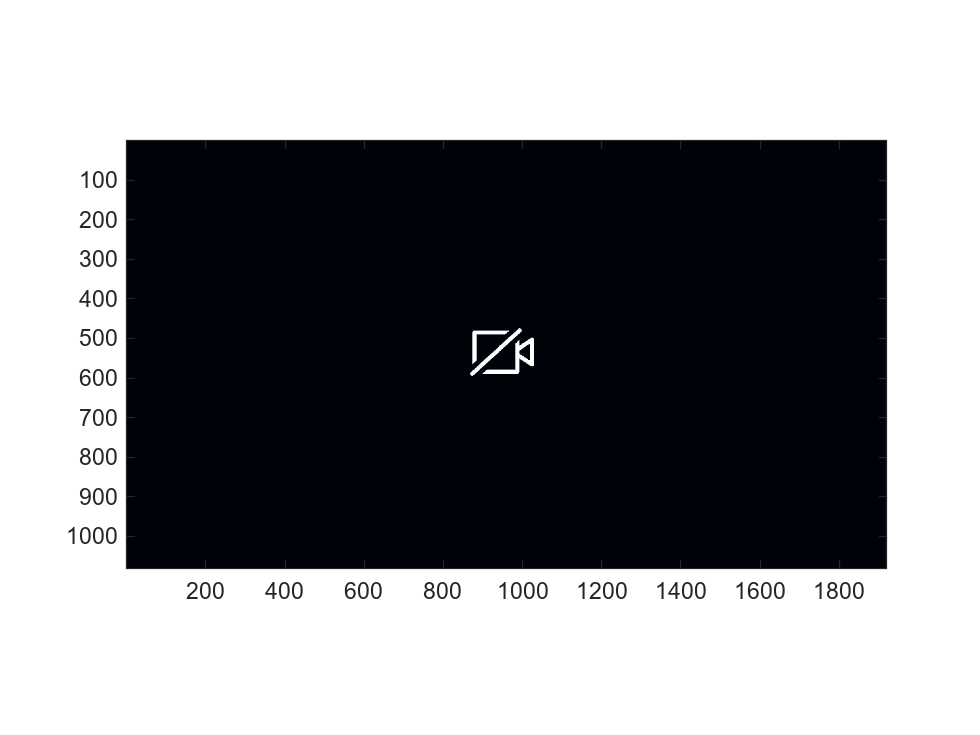

cam = webcam; 
loadedData = load("GraspPoint5.mat");
graspNet = loadedData.net;
yoloNet = yolov4ObjectDetector('tiny-yolov4-coco');

while true
    img = snapshot(cam);
    [bboxes] = detect(yoloNet, img, 'Threshold', 0.5);

   
    figure(1); clf; 
    image(img); axis image; hold on;

    for i = 1:size(bboxes, 1)
        box = bboxes(i, :);
        rectangle('Position', box, 'EdgeColor', 'r', 'LineWidth', 2);
        xStart = round(box(1));
        yStart = round(box(2));
        boxWidth = round(box(3));
        boxHeight = round(box(4));
        img2 = imresize(img(yStart:yStart+boxHeight, xStart:xStart+boxWidth, :), [224, 224]);

        predictedPoints = predict(graspNet, img2);
        scaleX = boxWidth / 224;
        scaleY = boxHeight / 224;
        predictedPointsTransformed = zeros(size(predictedPoints));
        predictedPointsTransformed(1:2:end) = predictedPoints(1:2:end) * scaleX + xStart;
        predictedPointsTransformed(2:2:end) = predictedPoints(2:2:end) * scaleY + yStart;

        for j = 1:3
            plot(predictedPointsTransformed(2*j-1), predictedPointsTransformed(2*j), 'go', 'MarkerSize', 2, 'LineWidth', 2);
        end
    end
    hold off;
    pause(0.1);
end